Příklady k Procvičení:

clear all;
close all;

# Náhodná veličina

## 1. Distribuční funkce

Příklad 4: Máte funkci y = 1 - exp(-t/a). Vykreslete graf funkce (funkce plot) a zjistěte, zda se skutečně jedná o distribuční funkci.

x=0:0.1:20;
y= 1 - exp(-x./3);
plot(x,y)
%jedná se odistribuční funkci

Příklad 5: Máte vygenerovaný soubor 10000 naměřených hodnot, který je uložen v P0305.mat. Vytvořte z nich distribuční funkci. Pro třídění dat použijte příkaz sort. Dále vytvořte z dat histogram o 50 sloupcích. 

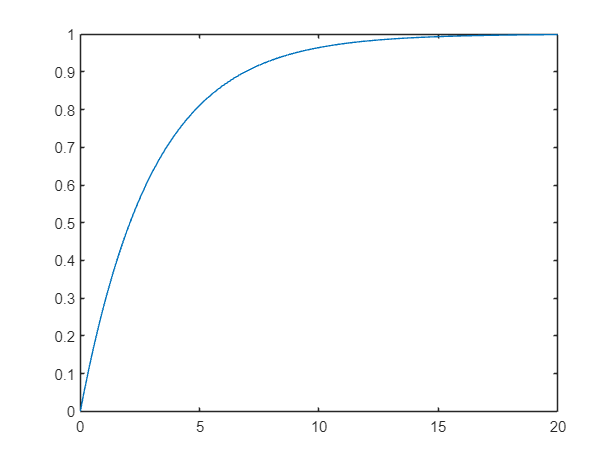

x = importdata("P0305.mat");
y = 0.00005:0.0001:0.99995;
x=sort(x);
hold on

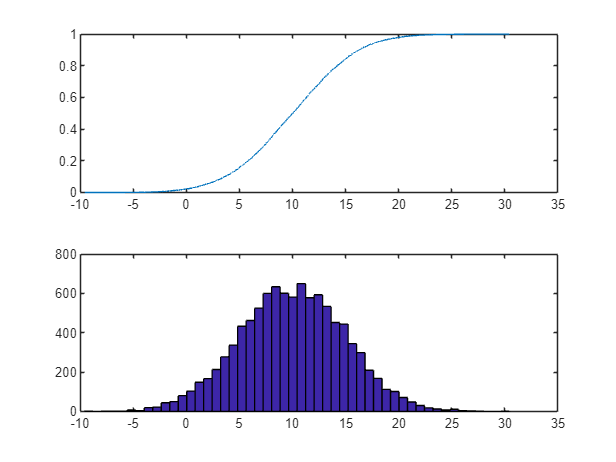

subplot(2,1,1)
plot(x,y)

subplot(2,1,2)
hist(x, 50)
hold off

Příklad 6: Máte výsledky 10000 hodů šestistěnnou kostkou. Data jsou uložena v P0306.mat. Vytvořte distribuční funkci z výsledků. 

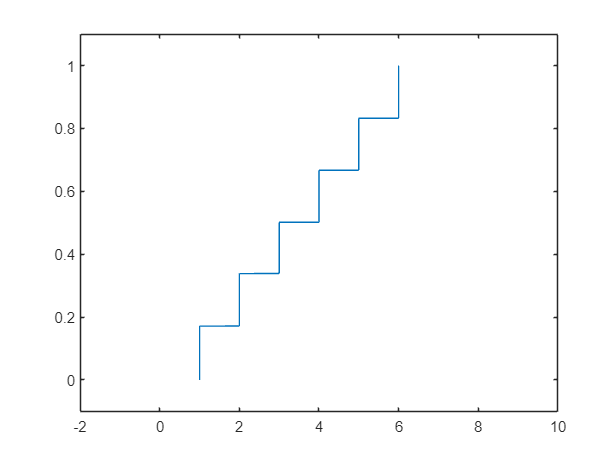

x=importdata("P0306.mat");
x=sort(x);
figure
plot(x,y)
axis([-2 10 -0.1 1.1])

## 3. Diskrétní veličina

Příklad 7: Nakreslete do grafu pravděpodobnostní funkci, která je dána předpisem P(x)=(10 nad x)(0.1^x)(0.9^(10-x)).

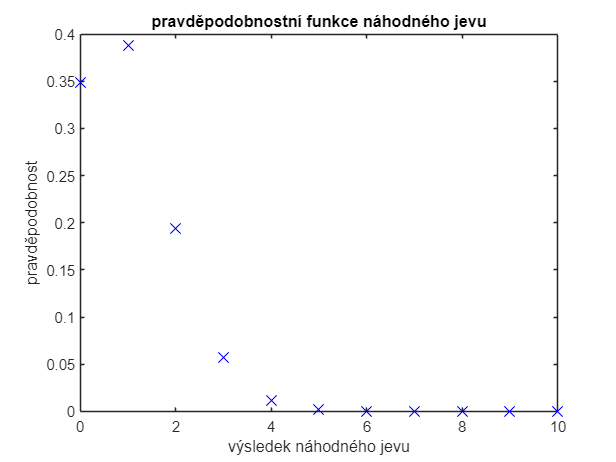

x=0:1:10;
y=[];
for i = 0:10
    y(i+1)=nchoosek(10, i)*0.1^i*0.9^(10-i);
end
figure
plot(x,y,'bx','MarkerSize',10)
title('pravděpodobnostní funkce náhodného jevu')
xlabel('výsledek náhodného jevu')
ylabel('pravděpodobnost')

Příklad 8: Obdrželi jste pravděpodobnostní funkci, která je dána v tabulce. Vytvořte graf pravděpodobnostní funkce. 

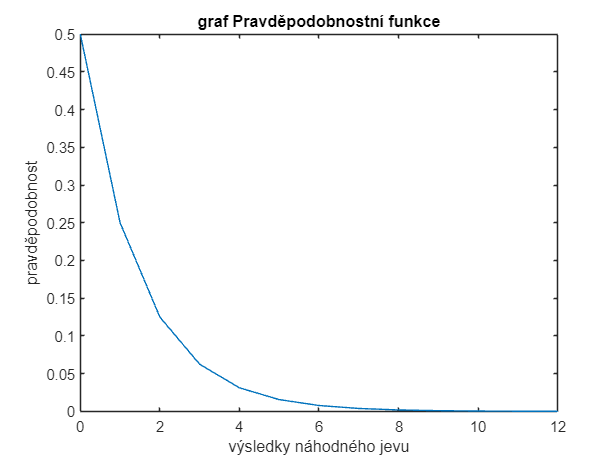

vstup = importdata("P0308.xlsx");
x=vstup.data.List1(1,:);
y=vstup.data.List1(2,:);
figure
plot(x,y,'MarkerSize',10)
title('graf Pravděpodobnostní funkce')
xlabel('výsledky náhodného jevu')
ylabel('pravděpodobnost')

Příklad 9: V souboru P0309.mat je 10000 naměřených dat. Vytvořte graf, kde budou vyobrazeny 4 histogramy. První bude obsahovat 10, druhý 100, třetí 500 a čtvrtý 5000 sloupců. Jaký byste z nich označily jako nejlepší?

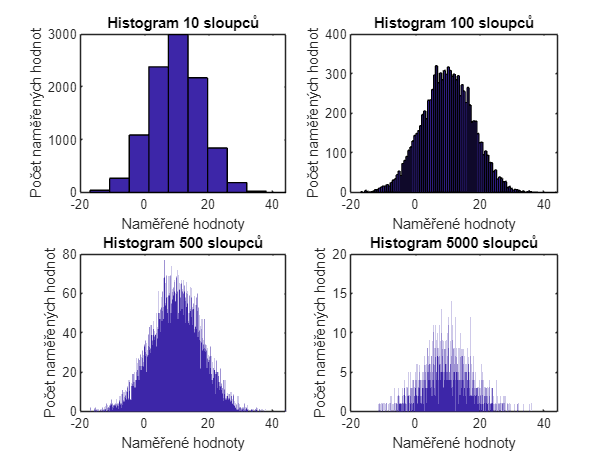

x = [];
x=importdata("P0309.mat");
figure
subplot(2,2,1)
hist(x,10);
title('Histogram 10 sloupců');
xlabel('Naměřené hodnoty');
ylabel('Počet naměřených hodnot');
subplot(2,2,2)
hist(x,100)
title('Histogram 100 sloupců');
xlabel('Naměřené hodnoty');
ylabel('Počet naměřených hodnot');
subplot(2,2,3)
hist(x,500)
title('Histogram 500 sloupců');
xlabel('Naměřené hodnoty');
ylabel('Počet naměřených hodnot');
subplot(2,2,4)
hist(x,5000)
title('Histogram 5000 sloupců');
xlabel('Naměřené hodnoty');
ylabel('Počet naměřených hodnot');

## 4. Spojitá náhodná veličina

Příklad 10: Máte distribuční funkci ve tvaru F(x) = 1-exp(-(a*x)^b), kde a,b>0. Vypočtěte hustotu distribuční funkce. Užijte knihovnu symbolic.

syms a b c;
y = 1-exp(-(a*c)^b)

$$y = 1-{\mathrm{e}}^{-{\left(a\,c\right)}^{b}}$$

z = diff(y)

$$z = a\,b\,{\mathrm{e}}^{-{\left(a\,c\right)}^{b}}\,{\left(a\,c\right)}^{b-1}$$

Příklad 11: Hustota pravděpodobnosti má tvar f(x) = lambda.exp(-lambda*t). Zjistěte distribuční funkci.

%pužijeme proměnných již vytvořených
%lambda = a
%t=b
f = a*exp(-a*b);
F = int(f);
limit(F,0); %limita musí být rovna 0
F=1+int(f)

$$F = 1-{\mathrm{e}}^{-a\,b}$$

limit(F,0);
limit(F,inf);

## 5. Funkce náhodné veličiny

Příklad 12: V souboru P0312.mat máte vygenerováno 1000 dvojic dat (první sloupec vektor x, druhý sloupec vektor y), která byla z rovnoměrného rozdělení v intervalu <0,1>. Nakreslete 4 grafy: 

- v prvním bude distribuční funkce náhodné veličiny z vektoru x, 

- v druhém bude distribuční funkce náhodné veličiny (x+y),

- ve třetím bude distribuční funkce náhodné veličiny (x*y),

- ve čtvrtém bude distribuční funkce náhodné veličiny (x/y). Vodorovnou osu dekadicky zlogaritmujte.

Uvědomte si, jaký vliv mají transformace náhodné proměnné na výsledky. Distribuční funkci můžete vygenerovat pomocí funkce ecdf.

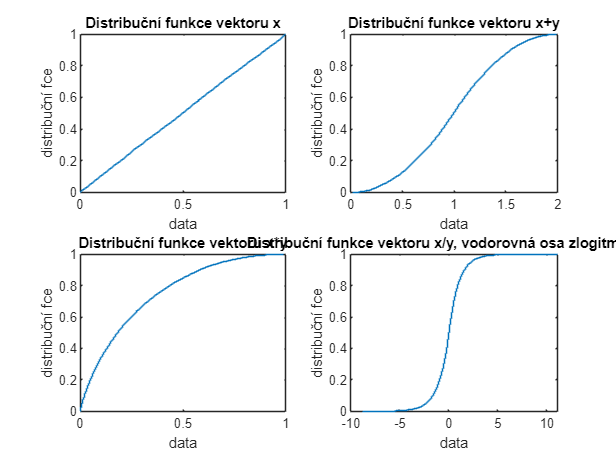

data = importdata('P0312.mat');
x=data(:,1);
y=data(:,2);

figure
subplot(2,2,1)
ecdf(x)
title('Distribuční funkce vektoru x');
xlabel('data')
ylabel('distribuční fce');

z=x+y;
subplot(2,2,2)
ecdf(z)
title('Distribuční funkce vektoru x+y');
xlabel('data')
ylabel('distribuční fce');

z=x.*y;
subplot(2,2,3)
ecdf(z)
title('Distribuční funkce vektoru x*y');
xlabel('data')
ylabel('distribuční fce');

z = x./y;
subplot(2,2,4)
ecdf(log(z))
title('Distribuční funkce vektoru x/y, vodorovná osa zlogitmovaná');
xlabel('data')
ylabel('distribuční fce');

## 6. Číselné charakteristiky náhodné veličiny

Příklad 14: Máte distribuční funkci ve tvaru F(x) = 1 - exp(-at). Uvažujte, že parametr a=0.1, 0.2 a 0.5 ( t>0). Vypočtěte hustotu pravděpodobnosti, intenzitu náhodného jevu (lambda = f(x)/(1-F(x))) , střední hodnotu, rozptyl, směrodatnou odchylku, šikmost a špičatost. Zkuste na základě výsledků odvodit vzorce pro výše uvedené veličiny. 

syms a t;
a=[0.1,0.2,0.5]

a =     0.1000    0.2000    0.5000


F=1-exp(-a*t);
f=diff(F);
lambda = f./(1-F)

$$lambda = \left(\begin{array}{ccc} \frac{1}{10} & \frac{1}{5} & \frac{1}{2} \end{array}\right)$$

E=int(t.*f,0,inf)

$$E = \left(\begin{array}{ccc} 10 & 5 & 2 \end{array}\right)$$

D=int((t-E).^2.*f,0,inf)

$$D = \left(\begin{array}{ccc} 100 & 25 & 4 \end{array}\right)$$

sikmost=int((t-E).^3.*f,0,inf)./(D.^1.5)

$$sikmost = \left(\begin{array}{ccc} 2 & 2 & 2 \end{array}\right)$$

spicatost = int((t-E).^4.*f,0,inf)./(D.^2)

$$spicatost = \left(\begin{array}{ccc} 9 & 9 & 9 \end{array}\right)$$

Příklad 15: Máte hustotu pravděpodobnosti ve tvaru f(x) = 1/(b-a), pro a<x<b. Vypočtěte střední hodnotu, rozptyl, směrodatnou odchylku, šikmost a špičatost. 

syms a x b;
f=1/(b-a);
strhod=int(x.*f,a,b)

$$strhod = \frac{a}{2}+\frac{b}{2}$$

rozptyl=int((x-strhod).^2.*f,a,b)

$$rozptyl = \frac{{\left(a-b\right)}^{2}}{12}$$

smerodch=sqrt(rozptyl)

$$smerodch = \sqrt{\frac{{\left(a-b\right)}^{2}}{12}}$$


tretimoment=int((x-strhod).^3.*f,a,b);
ctvrtymoment=int((x-strhod).^4.*f,a,b);

sikmost=tretimoment./smerodch.^3

$$sikmost = 0$$

spicatost=ctvrtymoment./smerodch.^4

$$spicatost = \frac{9}{5}$$

Příklad 16: Máte rozdělení s distribuční funkcí ve tvaru 1/2 + 1/pi*arctg(x/2). Zjistěte, zda se jedná o statistické rozdělení. Pokud ano, určete median a střední hodnotu. Nakreslete graf rozdělení.

syms x
F = 1/2 + 1/pi*atan(x/2);
lim_dol=limit(F,-inf)

$$lim\_dol = \frac{1}{2}-\frac{5734161139222659\,\pi }{36028797018963968}$$

lim_hor=limit(F,inf)

$$lim\_hor = \frac{5734161139222659\,\pi }{36028797018963968}+\frac{1}{2}$$

median = solve(F==0.5)

$$median = 0$$

f=diff(F)

$$f = \frac{5734161139222659}{36028797018963968\,\left(\frac{x^{2}}{4}+1\right)}$$


%rozdeleni je symetricke, ale neexistuje stredni hodnota. 
%protože integral nelze spočítat. Taková matematická hříčka 
EX=int(x*f,-inf,inf)

$$EX = \mathrm{NaN}$$

EX=simplify(EX)

$$EX = \mathrm{NaN}$$

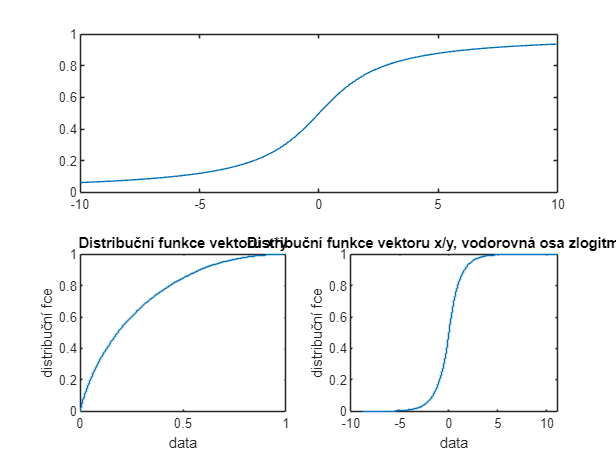


x=-10:0.1:10;
Fx=0.5+(atan(x/2))/pi();
subplot(2,1,1)
plot(x,Fx)


fx=1./(2*pi*(x.^2/4 + 1));
subplot(2,1,2)
plot(x,fx)

Příklad 16a: Náhodná veličina X má distribuční funkci x^2/4 na intervalu (0,2), nulovou pro x<0 a jednotkovou pro x>2. Najděte hustotu funkce, medián a střední hodnotu. Určete pravděpodobnost P(0.5<x<1.5)

syms x positive;
Fx=x^2/4

$$Fx = \frac{x^{2}}{4}$$

fx = diff(Fx)

$$fx = \frac{x}{2}$$

median=solve(Fx==0.5)

$$median = \sqrt{2}$$

Ex=int(fx,0,2)

$$Ex = 1$$

P = 1.5^2/4 - 0.5^2/4

P = 0.5000

Příklad 18: Náhodná veličina má distribuční funkci  F(x) = 1/8*x^3  , pro  . Určete střední hodnotu a rozptyl náhodné veličiny. Jaká je pravděpodobnost, že náhodná veličina bude mít výsledek v intervalech:

-  <0,1>

-  <0.5,1.5>

-  <0,1>U<1.5,2>

syms x;
F(x)=(x^3)/8;
%kontrola limit
limit(F(x),0)

$$ans = 0$$

limit(F(x),2)

$$ans = 1$$


f(x)=diff(F(x))

$$f(x) = \frac{3\,x^{2}}{8}$$


strhod=int(x.*f(x),0,2)

$$strhod = \frac{3}{2}$$

rozptyl = int((x-strhod).^2.*f(x),0,2)

$$rozptyl = \frac{3}{20}$$


%a)
x=0;
F0=F(x)

$$F0 = 0$$

x = 1;
F1=F(x)

$$F1 = \frac{1}{8}$$

Pa = F1 - F0

$$Pa = \frac{1}{8}$$


%b)
x=0.5;
F05=F(x)

$$F05 = \frac{1}{64}$$

x=1.5;
F15=F(x)

$$F15 = \frac{27}{64}$$

Pb = F15 - F05

$$Pb = \frac{13}{32}$$


%c)
x=2;
F2=F(x)

$$F2 = 1$$

P=Pa+(F2-F15)

$$P = \frac{45}{64}$$

Příklad 19: Nechť X je spojitá náhodná veličina definována hustotou pravděpodobnosti f(x): f(x) = c(2-x)(2+x).V intervalu <-2,2>. Hustota pravděpodobnosti je nulová jinde. Úkolem je 

- Nalézt konstantu c tak, aby f(x) byla korektně zadána. Uvažte, že při integraci přičítáte i posun.

- Nakreslit do jednoho grafu hustotu pravděpodobnosti a distribuční funkci 

- Určete pravděpodobnost P(X<0.3); P(0<X<1) a P(X>1)

syms x;
%nadefinuji distribu�n� funkci bez parametru c
%mohu p�edpokl�dat �e c=1 a dopo��t�m ho
fx=(2-x).*(2+x);

%a)
%spo��t�m integr�l od -2 do 2
Fx=int(fx,-2,2)

$$Fx = \frac{32}{3}$$

%dopo��t�m hodnotu c, tak aby distribu�n� funkce d�vala 1
c=1/Fx

$$c = \frac{3}{32}$$


%hustotu vyn�sob�m c
fx=c*(2-x).*(2+x)

$$fx = -\left(\frac{3\,x}{32}-\frac{3}{16}\right)\,\left(x+2\right)$$


%distribu�n� funkce
Fx=c*int(fx)

$$Fx = -\frac{3\,x\,\left(x^{2}-12\right)}{1024}$$

    %zji�t�n� posunu
posun=limit (Fx,-2)

$$posun = -\frac{3}{64}$$

Fx=-posun+c*int(fx)

$$Fx = \frac{3}{64}-\frac{3\,x\,\left(x^{2}-12\right)}{1024}$$

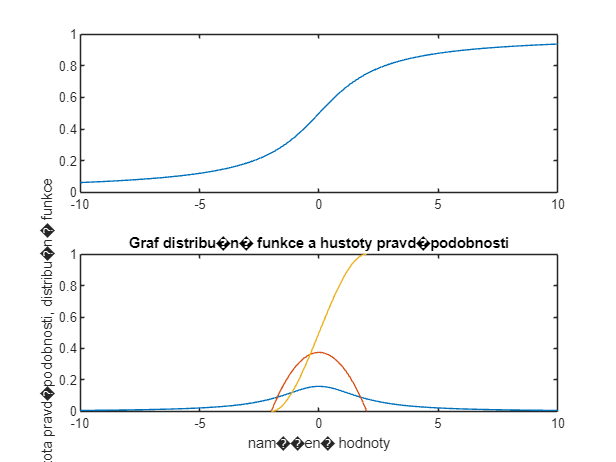

    %posun se rovn� 1/2

%b)
x=-2:0.01:2;
f=3./32.*(2-x).*(2+x);
F=-(x.*(x.^2 - 12))/32+0.5;
hold on
plot(x,f);
plot(x,F);
title ('Graf distribu�n� funkce a hustoty pravd�podobnosti')
xlabel('nam��en� hodnoty')
ylabel('hustota pravd�podobnosti, distribu�n� funkce')
hold off


%c)
x=0.3;
Pa=-(x.*(x.^2 - 12))/32+0.5

Pa = 0.6117


x=1;
Pb1=-(x.*(x.^2 - 12))/32+0.5;
x=0;
Pb0=(-(x.*(x.^2 - 12))/32+0.5);
Pb=Pb1-Pb0

Pb = 0.3438


x=1;
Pc=1-(-(x.*(x.^2 - 12))/32+0.5)

Pc = 0.1562

## 7. Statistické charakteristiky kvalitativních proměnných

Příklad 20: Vypočtěte pravděpodobnost, že uhádnete právě n čísel ve hře šťastných desek (viz příklad P0205). Výsledky zobrazte graficky. 

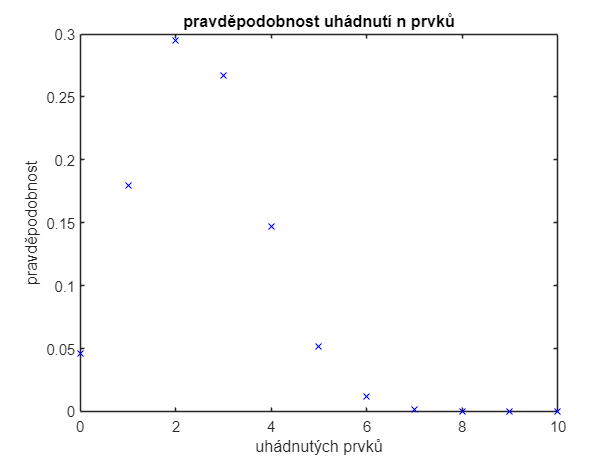

warning off
P5(1) = nchoosek(10,0)*nchoosek(70,20)/nchoosek(80,20);
P5(2) = nchoosek(10,1)*nchoosek(70,19)/nchoosek(80,20);
P5(3) = nchoosek(10,2)*nchoosek(70,18)/nchoosek(80,20);
P5(4) = nchoosek(10,3)*nchoosek(70,17)/nchoosek(80,20);
P5(5) = nchoosek(10,4)*nchoosek(70,16)/nchoosek(80,20);
P5(6) = nchoosek(10,5)*nchoosek(70,15)/nchoosek(80,20);
P5(7) = nchoosek(10,6)*nchoosek(70,14)/nchoosek(80,20);
P5(8) = nchoosek(10,7)*nchoosek(70,13)/nchoosek(80,20);
P5(9) = nchoosek(10,8)*nchoosek(70,12)/nchoosek(80,20);
P5(10) = nchoosek(10,9)*nchoosek(70,11)/nchoosek(80,20);
P5(11) = nchoosek(10,10)*nchoosek(70,10)/nchoosek(80,20);
warning on
x=0:1:10;
figure
plot(x,P5,'bx');
title('pravděpodobnost uhádnutí n prvků')
xlabel('uhádnutých prvků')
ylabel('pravděpodobnost')

Příklad 21: Předmět na univerzitě si zapsalo 80 studentů, z nichž 4 vykonaly zkoušku na první termín, 16 na druhý, 25 na třetí a 10 studentů zkoušku nesplnilo ani na třetí termín (sloupec 4). Zbytek studentů neobdržel zápočet (sloupec 5). Zjistěte relativní četnosti a vytvořte sloupcový graf výsledků. Vytvořte distribuční funkci pomocí funkce cdfplot a histogram (funkce hist). 

znamka = [1,2,3,4,5]

znamka =      1     2     3     4     5


student=[4,16,25,10,80-4-16-25-10]

student =      4    16    25    10    25


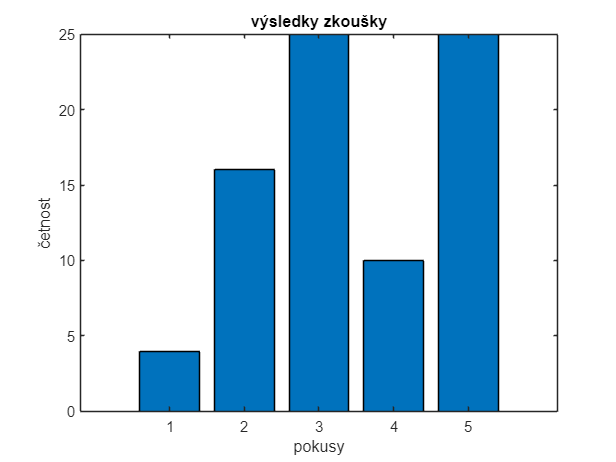

figure
bar(znamka, student);
title('výsledky zkoušky')
xlabel('pokusy')
ylabel('četnost')

data=[];
data(1:4)=1;
data(5:20)=2;
data(21:45)=3;
data(46:55)=4;
data(56:80)=5;
data

data =      1     1     1     1     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     4     4     4     4     4


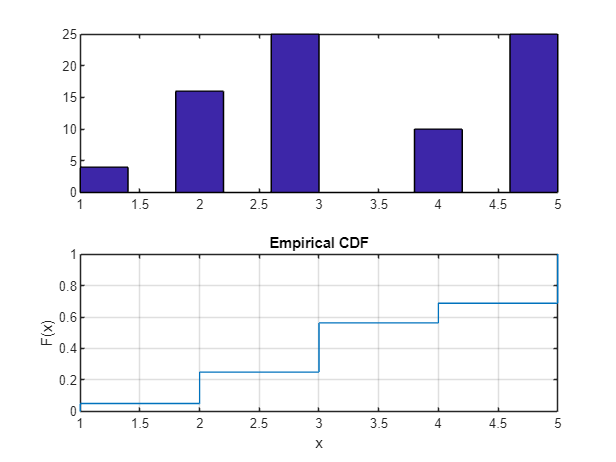

figure
subplot(2,1,1)
hist(data);
subplot(2,1,2)
cdfplot(data)

Příklad 23: Máte k dispozici záznamy o poruchách na jednotlivých zařízeních v rámci jednoho podniku (soubor P0323.xlsx). Data obsahují datum poruchy a typ zařízení, kde byla porucha nalezena. Vytvořte histogram pro poruchovost jednotlivých komponent.  

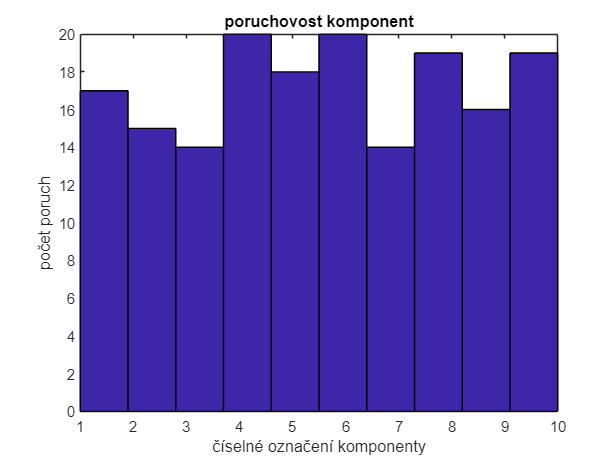

x = importdata('P0323.xlsx').data.List1(:,1);
figure
hist(x)
title('poruchovost komponent')
xlabel('číselné označení komponenty')
ylabel('počet poruch')

## 8. Statistické charakteristiky numerických proměnných

Příklad 24: Máte naměřená diskrétní data uložená v souboru P0326.xlsx. Zjistěte z nich střední hodnotu, medián, modus, rozptyl a směrodatnou odchylku. Pro kontrolu zkuste vytvořit histogram a distribuční funkci (příkaz cdfplot). Proveďte diskuzi, zda výsledky mohou být správné. 

clear median;
x = importdata('P0326.xlsx').List1(:,1);
strhod = mean(x)

strhod = 12.4436

median_x = median(x)

median_x = 11

modus = mode(x)

modus = 0

rozptyl = var(x)

rozptyl = 94.5644

smodch = std(x)

smodch = 9.7244

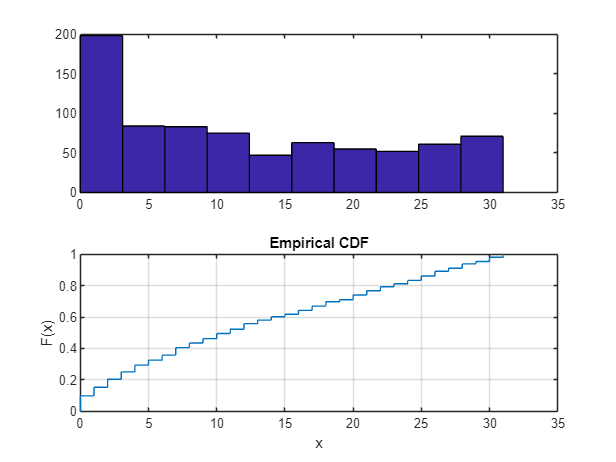


%kontrola
figure
subplot(2,1,1)
hist(x)
subplot(2,1,2)
cdfplot(x)

Příklad 27: Místní odborová organizace zveřejnila hrubé mzdy ve firmě, která jsou uložená v souboru P0327.xlsx. Zjistěte z nich aritmetický a geometrický průměr. Zjistěte medián, vytvořte histogram a distribuční funkci z naměřených dat. Proč není účelné zjišťovat modus. 

x = importdata('P0327.xlsx').List1(:,1);
ari_prum = mean(x)

ari_prum = 2.2815e+04

geom_prum = geomean(x)

geom_prum = 2.1374e+04

median_x = median(x)

median_x = 2.1579e+04

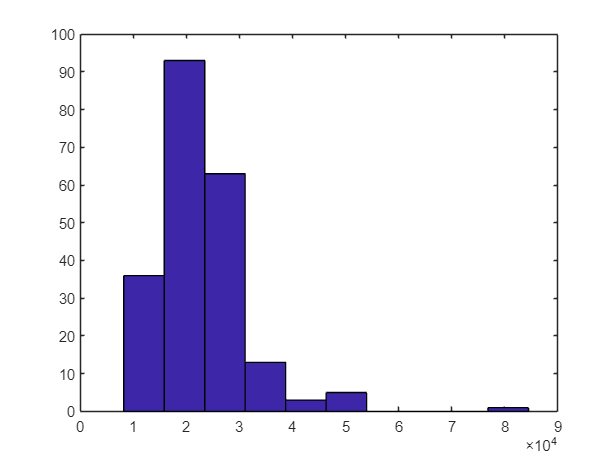

figure
hist(x)

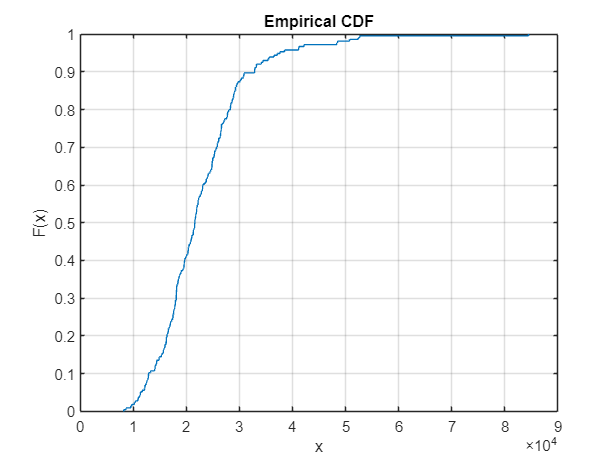

figure 
cdfplot(x)

Příklad 28: Máte data uložená v souboru 0328.mat. Zjistěte z nich aritmetický průměr a výběrový rozptyl. Dále určete 5% a 95% kvantil a dolní a horní kvartil. Jistě nepohrdnete i znalostí mediánu. Vytvořte empirickou distribuční funkci.

x = importdata('P0328.mat');
arit_prum = mean(x)

arit_prum = 964.0998

rozptyl = var(x)

rozptyl = 1.5413e+05

kv5 = prctile(x,5)

kv5 = 344.4757

kv95 = prctile(x,95)

kv95 = 1.6178e+03

kv50=prctile(x,50)

kv50 = 957.7050

dolkvart = prctile(x,25)

dolkvart = 681.5385

horkvart = prctile(x,75)

horkvart = 1.2557e+03

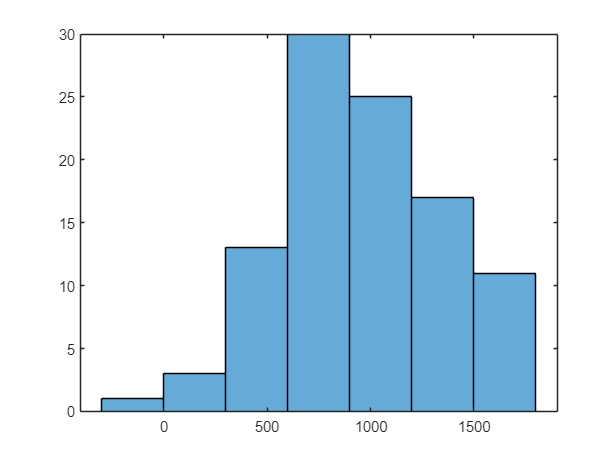


figure
histogram(x)

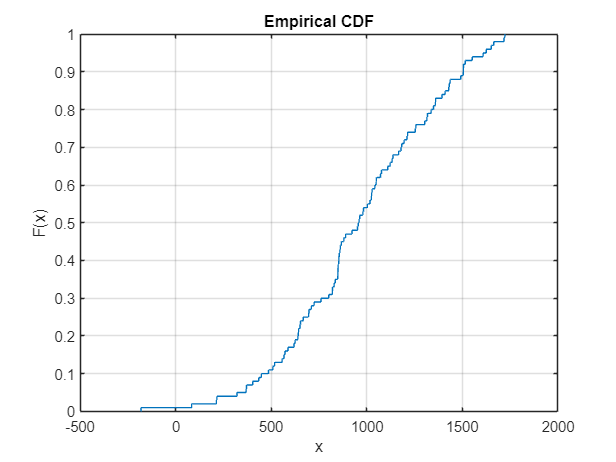

figure
cdfplot(x)

Příklad 30: Mějte výsledky měření z 5 aparatur, které jsou uloženy v souboru P0330.xlsx. Vypočtěte pro každý typ aparatury střední hodnotu, rozptyl a směrodatnou odchylku. 

x=importdata('P0330.xlsx').data.List1;
for i=1:5
    strhod(i)=nanmean(x(:,i));
    varhod(i)=nanvar(x(:,i));
    stdhod(i)=nanstd(x(:,i));
end
stdhod

stdhod =     1.6633    2.4244    1.5776    3.9370    1.1972


varhod

varhod =     2.7667    5.8778    2.4889   15.5000    1.4333


strhod

strhod =    12.9000   12.1000   13.6000   15.5000   12.9000


Příklad 31: Máte naměřená data uložená v souboru P0331.mat. Určete metodou vnitřní hradby, z-souřadnice a x0,5 souřadnice hranici pro odlehlá měření. Zkuste vysvětlit, proč zjištěná odlehlá data nejsou pomocí všech tří testů shodná. 

Pozn. Data vypadají obdobně, protože byly vygenerovány z normálního rozdělení.

x=importdata('P0331.mat');
%a) vnitrní hradby
xdolni1=quantile(x,0.25)-1.5*iqr(x)

xdolni1 = 686.3643

xhorni1=quantile(x,0.75)+1.5*iqr(x)

xhorni1 = 1.3082e+03


%b) z-souradnice
xdolni2=mean(x)-3*std(x)

xdolni2 = 677.4617

xhorni2=mean(x)+3*std(x)

xhorni2 = 1.3117e+03


%c) 0.5 souradnice
xdolni3=median(x)-3*1.483*mad(x)

xdolni3 = 610.0543

xhorni3=median(x)+3*1.483*mad(x)

xhorni3 = 1.3660e+03

Příklad 32: Máte naměřená data, která jsou uložena v souboru P0332.mat. Zjistěte 5%, 50% a 95% kvantil těchto hodnot. Užijte funkci quantile. Vykreslete distribuční funkci z naměřených dat. 

x = importdata('P0332.mat');
q5 = quantile(x,0.05)

q5 = 10.8229

q50 = quantile(x,0.5)

q50 = 24.0838

q95 = quantile(x,0.95)

q95 = 37.3998

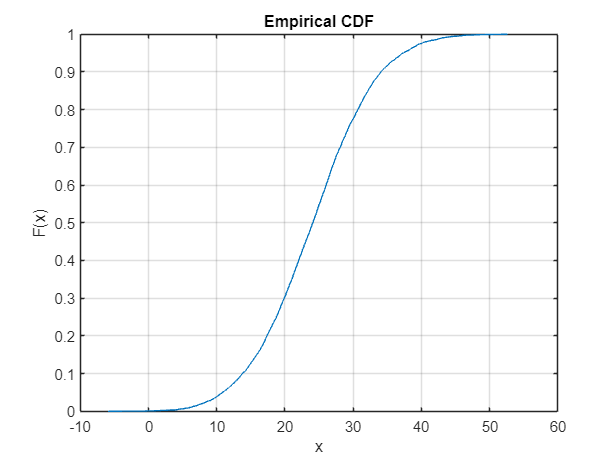

figure 
cdfplot(x)

Příklad 33: Máte naměřená data, která jsou uložena v souboru P0333.mat. Zjistěte 5%, 50% a 95% kvantil těchto hodnot. Určete střední hodnotu a median. Zkuste zauvažovat, co značí výrazná odlišnost střední hodnoty a mediánu. Může Vám pomoci histogram, použijte 50 sloupců. 

x=importdata("P0333.mat");
q5 = quantile(x,0.05)

q5 = 1.5832

q50 = quantile(x,0.5)

q50 = 117.8522

q95 = quantile(x,0.95)

q95 = 1.3029e+04

strhod = mean(x)

strhod = 2.0213e+03

median_x = median(x)

median_x = 117.8522

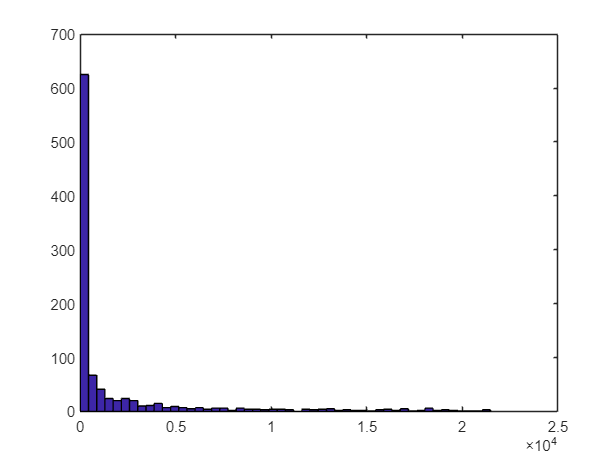

figure
hist(x,50)

%data jsou nesymetrická